(a)

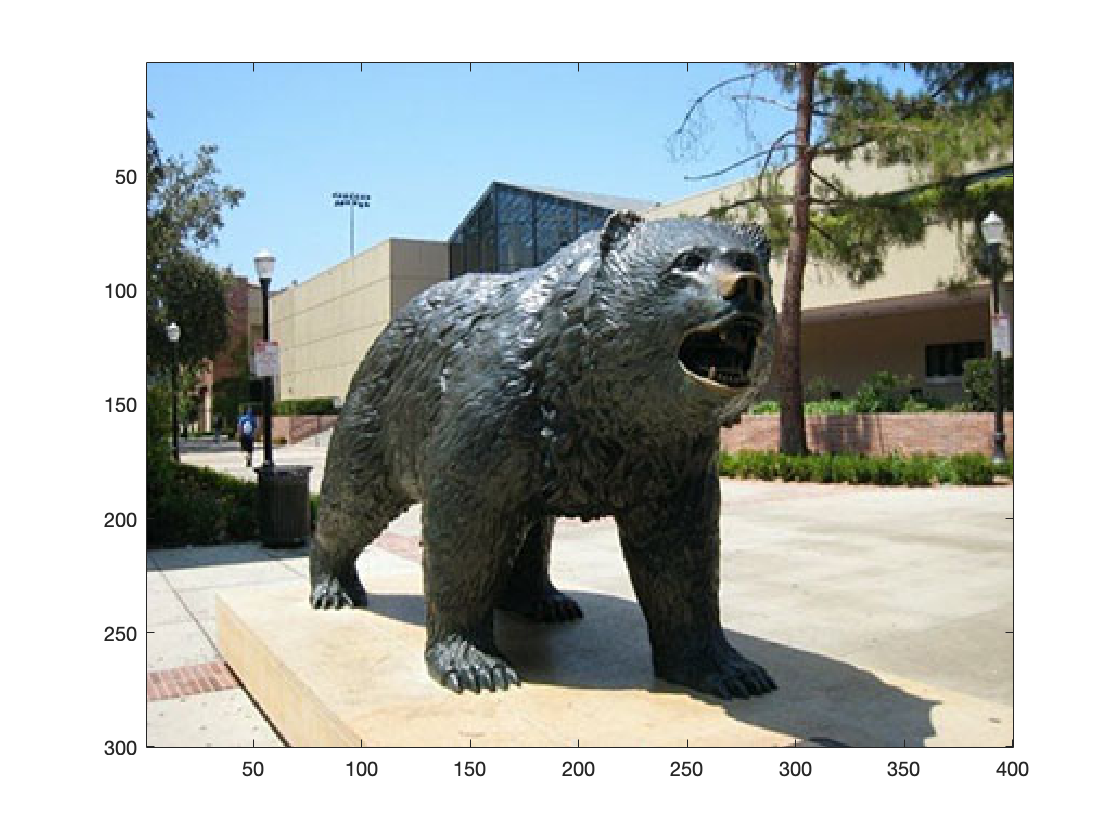

bruin = imread("UCLA_Bruin.jpg");
image(bruin);

n = size(bruin, 1);
m = size(bruin, 2);

(b)

K = 4;
mu = zeros(K, 3);
mu(1,:) = bruin(1,1,:);

for k = 2:K
    maxd = -1;
    for x = 1:n
        for y = 1:m
            mind = 1e9;
            cxy = zeros(1, 3);
            cxy(:) = bruin(x,y,:);
            for kp = 1:(k-1)
                mind = min(norm(cxy - mu(kp,:))^2, mind);
            end
            if (maxd < mind)
                maxd = mind;
                mu(k,:) = cxy(:);
            end
        end
    end
end
mu

mu =    147   200   250
     0     0     0
   137   141    57
    31    70   125


r = zeros(300, 400, K);
J = zeros(10, 1);
for iter = 1:10
    for x = 1:n
        for y = 1:m
            cxy = cast(squeeze(bruin(x,y,:)), 'double');
            mind = 1e9;
            mink = 0;
            for kp = 1:K
                dist = norm(cxy - mu(kp,:)');
                if (mind > dist)
                    mind = dist;
                    mink = kp;
                end
            end
            for kp = 1:K
                r(x, y, kp) = 0;
            end
            r(x, y, mink) = 1;
        end
    end
    for k = 1:K
        mean = zeros(1, 3);
        count = 0;
        for x = 1:n
            for y = 1:m
                cxy = cast(squeeze(bruin(x,y,:)), 'double');
                mean = mean + r(x, y, k) * cxy';
                count = count + r(x, y, k);
            end
        end
        mu(k,:) = mean / count;
    end
    sum = 0;
    for x = 1:n
        for y = 1:m
            cxy = cast(squeeze(bruin(x,y,:)), 'double');
            for k = 1:K
                sum = sum + r(x, y, k) * norm(cxy - mu(k,:))^2;
            end
        end
    end
    J(iter) = sum;
end
J(10)

ans = 5.8770e+08

mu

mu =   205.3092  218.2813  218.4876
   33.6186   36.2153   27.3633
  134.5668  136.7124  130.2239
   77.8911   83.4243   72.4920


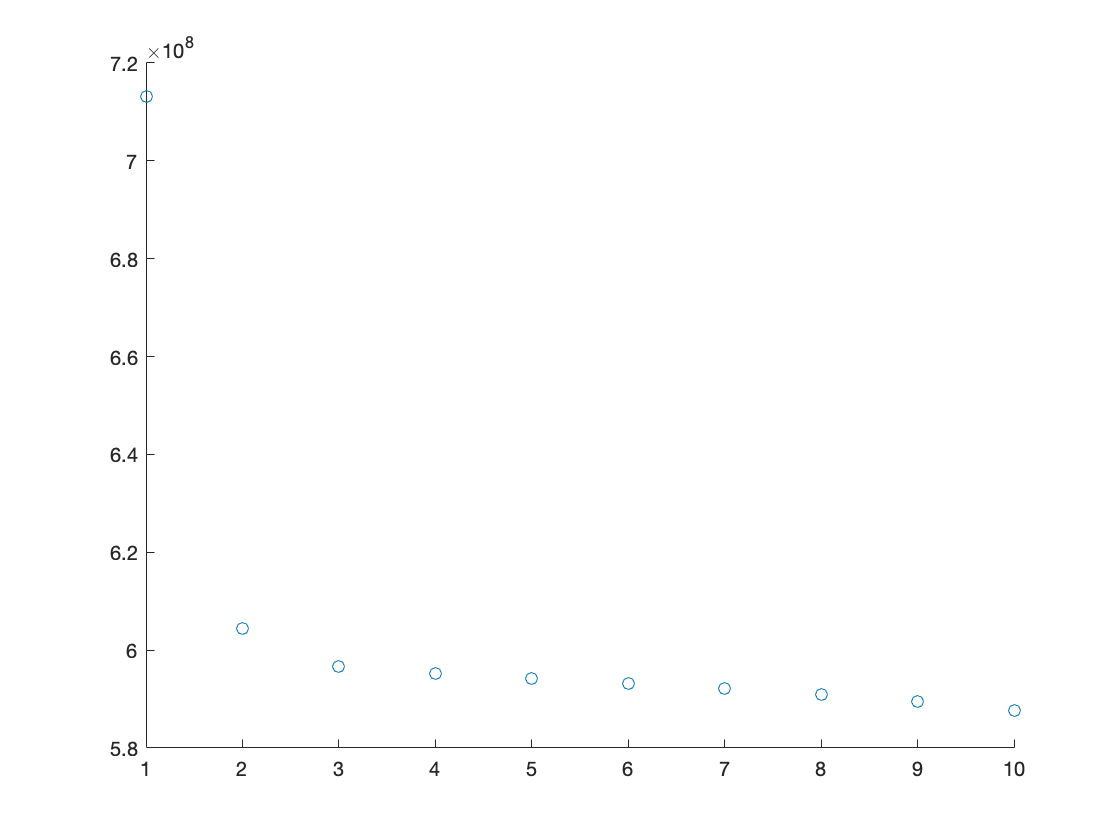

newbruin = bruin;
for x = 1:n
    for y = 1:m
        kp = 0;
        for k = 1:K
            if r(x, y, k) == 1
                newbruin(x, y, :) = mu(k,:);
            end
        end
    end
end
scatter(1:10, J);

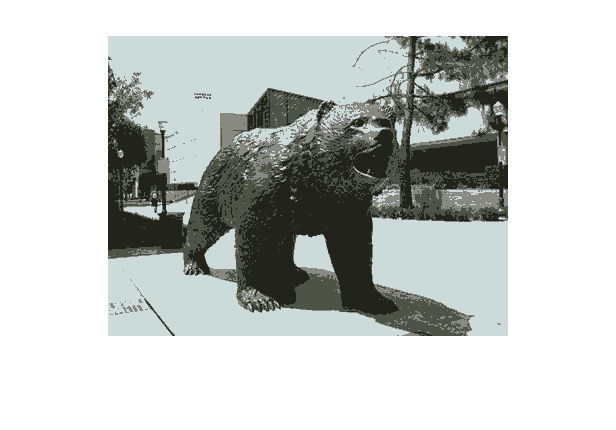

imshow(newbruin);

(c)

K = 8;
mu = zeros(K, 3);
mu(1,:) = bruin(1,1,:);

for k = 2:K
    maxd = -1;
    for x = 1:n
        for y = 1:m
            mind = 1e9;
            cxy = zeros(1, 3);
            cxy(:) = bruin(x,y,:);
            for kp = 1:(k-1)
                mind = min(norm(cxy - mu(kp,:))^2, mind);
            end
            if (maxd < mind)
                maxd = mind;
                mu(k,:) = cxy(:);
            end
        end
    end
end
mu

mu =    147   200   250
     0     0     0
   137   141    57
    31    70   125
   251   214   159
   109   139   165
    69    81     0
   242   255   255


r = zeros(300, 400, K);
J = zeros(10, 1);
for iter = 1:10
    for x = 1:n
        for y = 1:m
            cxy = cast(squeeze(bruin(x,y,:)), 'double');
            mind = 1e9;
            mink = 0;
            for kp = 1:K
                dist = norm(cxy - mu(kp,:)');
                if (mind > dist)
                    mind = dist;
                    mink = kp;
                end
            end
            for kp = 1:K
                r(x, y, kp) = 0;
            end
            r(x, y, mink) = 1;
        end
    end
    for k = 1:K
        mean = zeros(1, 3);
        count = 0;
        for x = 1:n
            for y = 1:m
                cxy = cast(squeeze(bruin(x,y,:)), 'double');
                mean = mean + r(x, y, k) * cxy';
                count = count + r(x, y, k);
            end
        end
        mu(k,:) = mean / count;
    end
    sum = 0;
    for x = 1:n
        for y = 1:m
            cxy = cast(squeeze(bruin(x,y,:)), 'double');
            for k = 1:K
                sum = sum + r(x, y, k) * norm(cxy - mu(k,:))^2;
            end
        end
    end
    J(iter) = sum;
end
J(10)

ans = 4.7337e+08

mu

mu =   168.8847  217.7350  250.7417
   22.0897   25.8861   19.4480
  105.9684  111.8957  105.6784
   78.3522   84.3161   72.1193
  207.4103  199.6460  179.9658
  153.6260  155.0707  150.9627
   53.1262   54.7085   42.1512
  235.8857  228.0374  209.6141


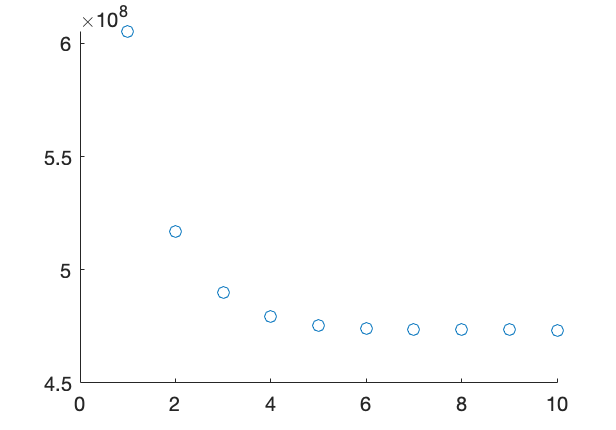

newbruin = bruin;
for x = 1:n
    for y = 1:m
        kp = 0;
        for k = 1:K
            if r(x, y, k) == 1
                newbruin(x, y, :) = mu(k,:);
            end
        end
    end
end
scatter(1:10, J);

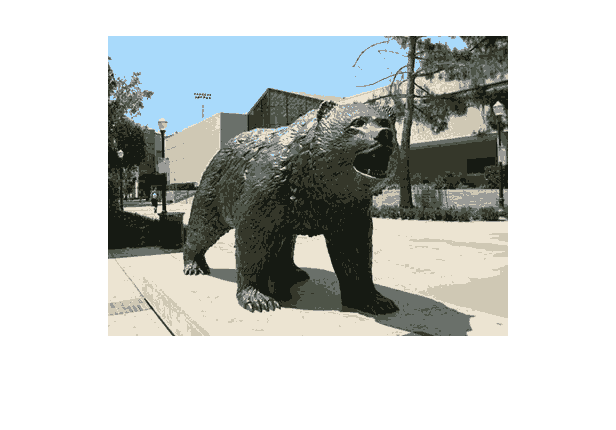

imshow(newbruin);

K = 16;
mu = zeros(K, 3);
mu(1,:) = bruin(1,1,:);

for k = 2:K
    maxd = -1;
    for x = 1:n
        for y = 1:m
            mind = 1e9;
            cxy = zeros(1, 3);
            cxy(:) = bruin(x,y,:);
            for kp = 1:(k-1)
                mind = min(norm(cxy - mu(kp,:))^2, mind);
            end
            if (maxd < mind)
                maxd = mind;
                mu(k,:) = cxy(:);
            end
        end
    end
end
mu

mu =    147   200   250
     0     0     0
   137   141    57
    31    70   125
   251   214   159
   109   139   165
    69    81     0
   242   255   255
   196   144   130
    96    69    76


r = zeros(300, 400, K);
J = zeros(10, 1);
for iter = 1:10
    for x = 1:n
        for y = 1:m
            cxy = cast(squeeze(bruin(x,y,:)), 'double');
            mind = 1e9;
            mink = 0;
            for kp = 1:K
                dist = norm(cxy - mu(kp,:)');
                if (mind > dist)
                    mind = dist;
                    mink = kp;
                end
            end
            for kp = 1:K
                r(x, y, kp) = 0;
            end
            r(x, y, mink) = 1;
        end
    end
    for k = 1:K
        mean = zeros(1, 3);
        count = 0;
        for x = 1:n
            for y = 1:m
                cxy = cast(squeeze(bruin(x,y,:)), 'double');
                mean = mean + r(x, y, k) * cxy';
                count = count + r(x, y, k);
            end
        end
        mu(k,:) = mean / count;
    end
    sum = 0;
    for x = 1:n
        for y = 1:m
            cxy = cast(squeeze(bruin(x,y,:)), 'double');
            for k = 1:K
                sum = sum + r(x, y, k) * norm(cxy - mu(k,:))^2;
            end
        end
    end
    J(iter) = sum;
end
J(10)

ans = 4.4759e+08

mu

mu =   169.4358  218.6251  251.6993
   17.7295   21.7464   16.2366
  109.1421  109.8681   70.8890
   63.4478   77.9096   86.0944
  233.2694  222.1816  198.6191
  129.6679  146.0076  157.9573
   58.2489   58.8509   45.5631
  238.0500  234.0214  221.4212
  188.7162  172.5177  152.1534
   81.2063   81.7605   58.6404


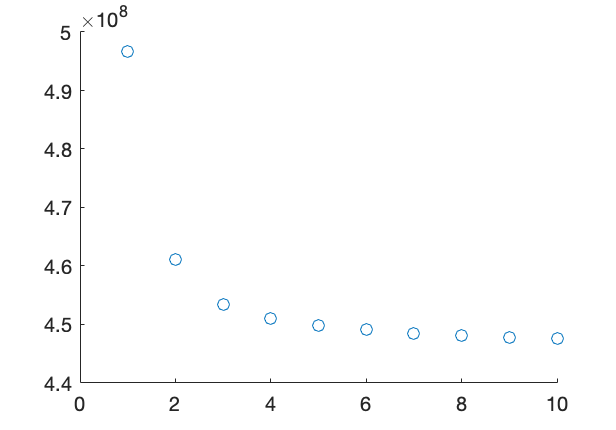

newbruin = bruin;
for x = 1:n
    for y = 1:m
        kp = 0;
        for k = 1:K
            if r(x, y, k) == 1
                newbruin(x, y, :) = mu(k,:);
            end
        end
    end
end
scatter(1:10, J);

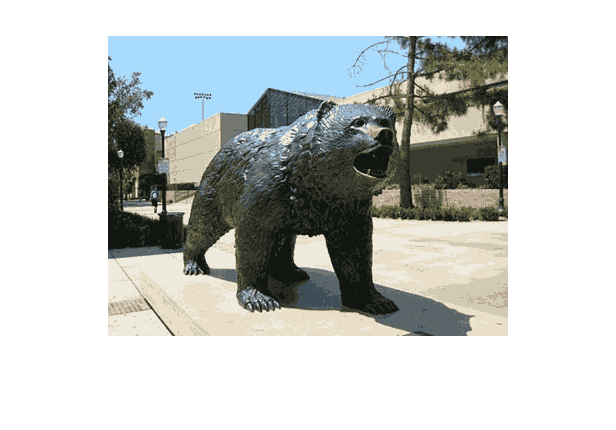

imshow(newbruin);

(d)

The original image is 300 * 400 * 3 * 8 = 2880000 bits needed. After the K-means algorithm the image is compressed and only relates to the size of the r matrix and the number of centers. 

K = 4 needs 4 * 3 * 8 for the 4 centers, and 300 * 400 * 2 = 240000 bits approximately. The compression ratio is about 12:1

K = 8 needs approximately 300 * 400 * 3 = 360000 bits. The compression ratio is about 8:1

K = 16 needs approx 300 * 400 * 4 = 480000 bits. The compression ratio is about 6:1. 